# **TU: ODE-IVP - Part 1**

**Numerical Programming: Y.-K. Kim**

Mod. 2024.10

# **I. 1st order ODE-IVP**

## Problem

Solve for the response (Vout) of an RC circuit with a sinusoidal input (Vin), from t=0 to 0.1 sec.

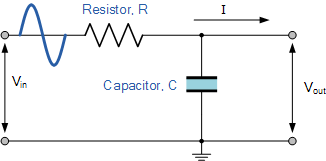

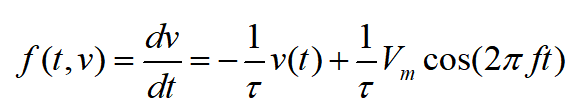

where 

RC=tau=0.01;  T=1/tau; 

f=100; Vm=1; w=2*pi*f;

## Part 1. MATLAB Tutorial

### Initial Condition

% Initial Condition
% time
a=0; b=0.1; 
h=0.001; 
t=a:h:b;
N = (b-a)/h;

% IVP-Initial Condition
v0 = 0;
y0= v0;

### Analytical Solution (Ground-truth)

The true analytical solution can be expressed as

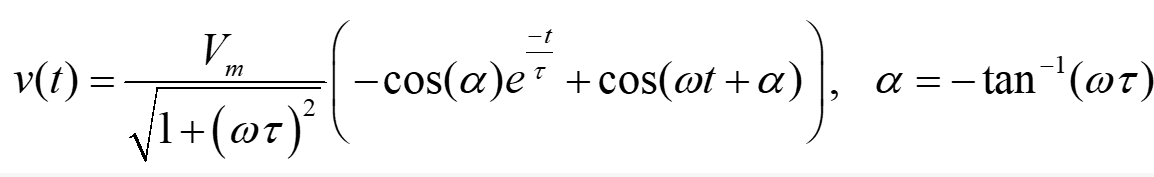

% Analytical Solution
tau=0.01; f=100; Vm=1; w=2*pi*f;

A=Vm/(sqrt(1+(w*tau)^2));
alpha=-atan(w*tau);

v_true=A*(-cos(alpha)*exp(-t/tau)+cos(w*t+alpha));



### MATLAB : ode45()

Lets define the RC circuit ODE function  f(t,v) as  odeFunc**_RC(t,v).**

*See ****Function Definition*** ***Section**** at the end of this tutorial file*


% odeFunc_RC.m

% function dvdt = odeFunc_RC(t,v)
%    tau=0.01; f=100; Vm=1;
%    dvdt =-v/tau + (1/tau)*Vm*cos(2*pi*f*t);
% end


Use ode45() or other similar functions to solve.

Type  `doc ode45` in the commpand prompt to read more about this function.

%% MATLAB's function ODE45
[tmat,vmat] = ode45(@odeFunc_RC, [a b], v0);  


Plot and compare with analytical solution

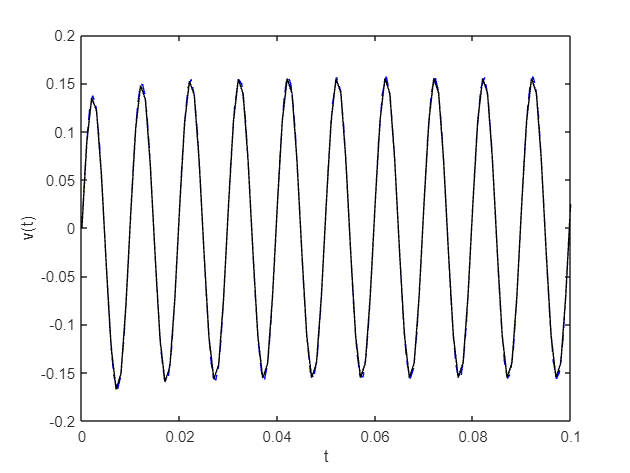

figure()
plot(tmat,vmat,'--b',t,v_true,'k')
xlabel('t'); ylabel('v(t)')

## Exercise 

#### Exercise 1:  Euler's Explicit Method

[t, yE] = odeEU(@odeFunc_RC,a,b,h,y0)

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


yE =          0    0.1000    0.1709    0.1847    0.1353    0.0409   -0.0632   -0.1378   -0.1549   -0.1085   -0.0168    0.0849    0.1573    0.1725    0.1244    0.0310   -0.0721   -0.1458   -0.1621   -0.1150   -0.0226    0.0797    0.1526    0.1682    0.1205    0.0276   -0.0752   -0.1486   -0.1646   -0.1173   -0.0246    0.0778    0.1510    0.1668    0.1192    0.0264   -0.0763   -0.1495   -0.1655   -0.1180   -0.0253    0.0772    0.1504    0.1662    0.1187    0.0259   -0.0767   -0.1499   -0.1658   -0.1183


Plot and compare with analytical solution

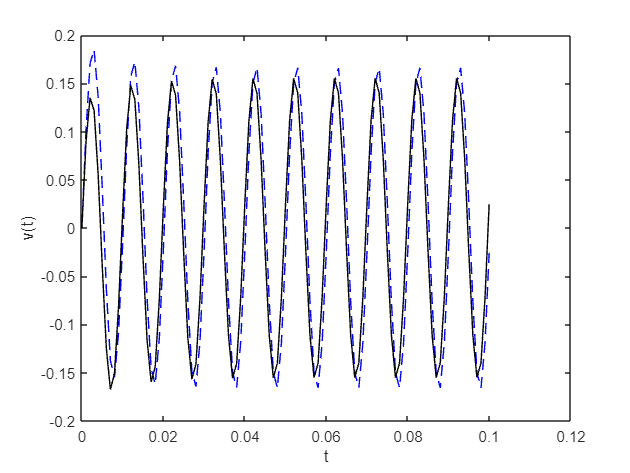

figure()
plot(t,yE,'--b',t,v_true,'k')
xlabel('t'); ylabel('v(t)')

Also, create the function file as `odeEU.m`** . **

`> See the example code file   ``odeEU_student.m` 

[t, yE] = odeEU_22000664(@odeFunc_RC,a,b,h,y0);

figure()
plot(t,yE,'--b',t,v_true,'k')
xlabel('t'); ylabel('v(t)')

#### Exercise 2: Euler's Modified Method

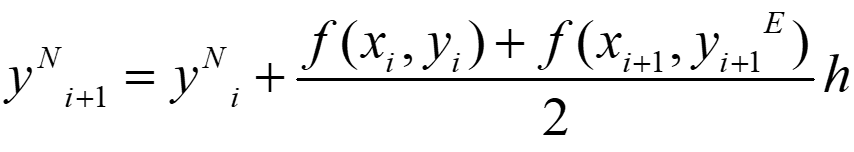

**Create odeEM_student.m**

Modify  the given template code

[t, yEM] = odeEM_22000664(@odeFunc_RC,a,b,h,y0);


Plot and compare with analytical solution

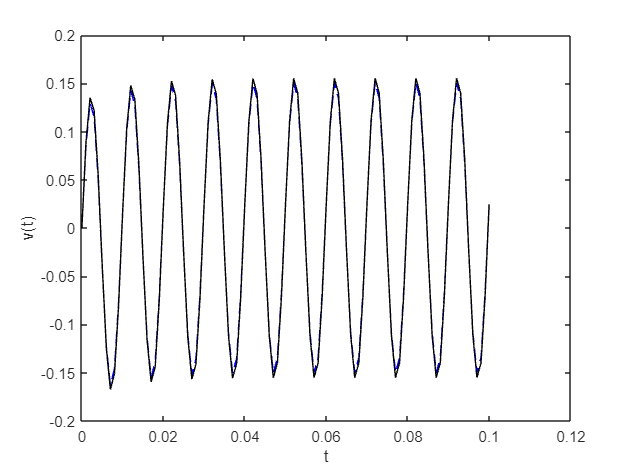

figure()
plot(t,yEM,'--b',t,v_true,'k')
xlabel('t'); ylabel('v(t)')

#### Exercise 3: 2nd Order Runge-Kutta

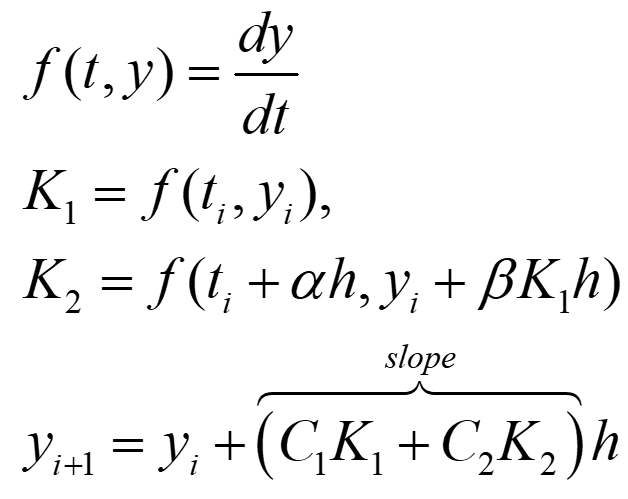

Let alpha=1, C1=0.5, C2=0.5. 

**Create odeRK2.m**

 Modify  the given template code

[t, yRK2] = odeRK2_22000664(@odeFunc_RC,a,b,h,y0);

Plot and compare with analytical solution

figure()
plot(t,yRK2,'--b',t,v_true,'k')
xlabel('t'); ylabel('v(t)')

#### Exercise 4: 4th Order Runge-Kutta

**Create odeRK4.m**

[t, yRK4] = odeRK4_22000664(@odeFunc_RC,a,b,h,y0);

Plot and compare with analytical solution

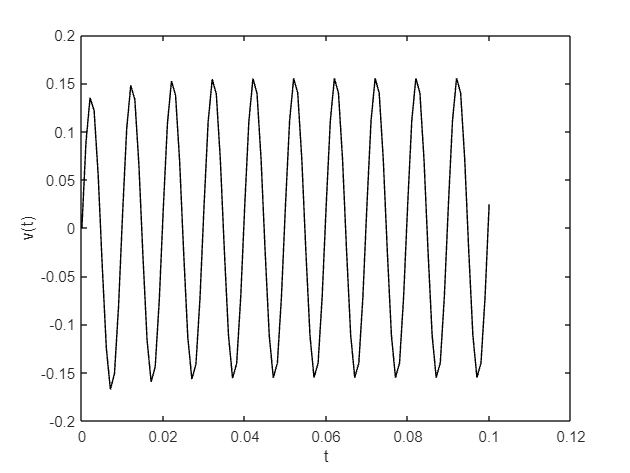

figure()
plot(t,yRK4,'--b',t,v_true,'k')
xlabel('t'); ylabel('v(t)')

# Function Definitions

**odeFunc_RC.m**

Lets define the RC circuit ODE function  f(t,v) as  odeFunc**_RC(t,v)**

function dvdt = odeFunc_RC(t,v)
   tau=0.01; f=100; Vm=1;
   dvdt =-v/tau + (1/tau)*Vm*cos(2*pi*f*t);   
end


**odeEU.m**

`[t, yE] = odeEu(@odeFunc_RC,a,b,h,y0)`

function [t, yE] = odeEU(ODE,a,b,h,y0)

    % Variable Initialization
    N = (b-a)/h;
    yE=zeros(1,N+1);
    t=zeros(1,N+1);

    % Initial Condition
    yE(1) = y0;
    t(1)=a;
    
    % Euler Explicit ODE Method
    for i = 1:N
        % Calculate: t(i+1)=_________
        % [TO-DO] your code goes here
        t(i+1) = t(i) + h;
                
        % Estimate: yE(i+1)=________
        % [TO-DO] your code goes here    
        yE(i+1) = yE(i) + ODE(t(i), yE(i))*h;
    end

% end  % End of Function
end